% 计算平均车费
avg_fee = sum(taxi_destination.cost)/length(taxi_destination.cost)

avg_fee = 104.4000


for salary_per_minute = [0.55,0.6,0.65,0.7,0.75,0.8]
    % 计算司机所能容忍的最大等待时间
    ideal_wait =  round(avg_fee/salary_per_minute)
    % 取2019年9月12月23点到2019年9月13月24点的时间序列，
    % 假设旅客从航班抵达到出租车上车点花费delay分钟，则
    % 序列往后平移delay分钟
    delay = 30
    t1 = datetime(2019,9,12,23,0,0);
    t2 = datetime(2019,9,13,23,59,59);
    t = (t1:minutes(1):t2)';
    t = arrayfun(@(x) x + minutes(delay),t);
    % 所有航班的旅客到达出租车上车点的时刻，通过平移得到
    offboard = flights_count.time;
    offboard = arrayfun(@(x) x + minutes(delay),offboard);
    % 旅客乘坐的士的概率，数据来自《白云机场旅客抵离方式选择研究》
    taxi_rate = 0.1356
    % 旅客上车点数量，数据来自白云机场官网
    exit = 6
    % 出租车乘客上客时间（分钟），数据来自《综合客运枢纽出租车上客点管理模式和效率分析》
    waste_time_per_taxi = 20/60;
    taxi_per_minute = 1/waste_time_per_taxi

    % 每辆出租车平均载客量，数据来自《基于时空消耗理论的多航站楼机场车道边容量评估》
    person_per_taxi = 1.7
    % 每个出口每分钟乘坐出租车离开的人数
    consume_person = taxi_per_minute * person_per_taxi
    % 客座率，数据来自CEIC数据库，选取最近五年
    load_factor = sum(load_factor_data.Data(end-4:end))/5 * 0.01
    
    % 客机平均座位数，数据来自白云机场官网2019年9月12日的所有航班的飞机型号统计
    seats = sum(plane_type.seats.*plane_type.number)/sum(plane_type.number);
    % 每个出口的人数
    person_per_flight = seats * load_factor / exit
    
    taxi_intended_per_minute = zeros(length(t),1);
    result = zeros(length(t),1);
    
    % 每个出口的需要乘坐出租车的人数
    taxi_intended_per_flight = taxi_rate*person_per_flight;
    % 第一分钟的需要乘坐出租车的人数
    result(1) = taxi_intended_per_flight * flights_count.flights(1);
    taxi_intended_per_minute(1) = taxi_intended_per_flight * flights_count.flights(1);
    % 计算第二分钟以后的需要乘坐出租车的人数
    for i = 2:length(t)
        if result(i-1) - consume_person < 0
            
            result(i) = 0;
        else
            result(i) = result(i-1) - consume_person;
        end
        if find(offboard==t(i))
            index = find(offboard==t(i));
            result(i) = result(i) + taxi_intended_per_flight * flights_count.flights(index);
            taxi_intended_per_minute(i) = taxi_intended_per_flight * flights_count.flights(index);
        end
        
    end
    
    % 计算未来最大等待时间内，无人排队乘出租车的时间
    t_blank = zeros(length(t)-ideal_wait,1);
    for i = 1:length(t)-ideal_wait
        t_blank(i) = 0;
        for j = 1:ideal_wait
            if result(i+j)==0
                t_blank(i) = t_blank(i) + 1;
            end
        end
    end
    

    % 计算司机所能容忍的最大车辆数目
    ideal_taxi_number = (ideal_wait - t_blank) /  waste_time_per_taxi;
    plot(t(1:length(ideal_taxi_number)),ideal_taxi_number)
    title('出租车扣除油耗的每分钟营运收益灵敏度分析')
    ylabel('X_m_a_x_车(t)/分钟')
    xlabel('t/分钟')
    hold on
end

ideal_wait = 190

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

ideal_wait = 174

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

ideal_wait = 161

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

ideal_wait = 149

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

ideal_wait = 139

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

ideal_wait = 131

delay = 30

taxi_rate = 0.1356

exit = 6

taxi_per_minute = 3

person_per_taxi = 1.7000

consume_person = 5.1000

load_factor = 0.8250

person_per_flight = 27.6548

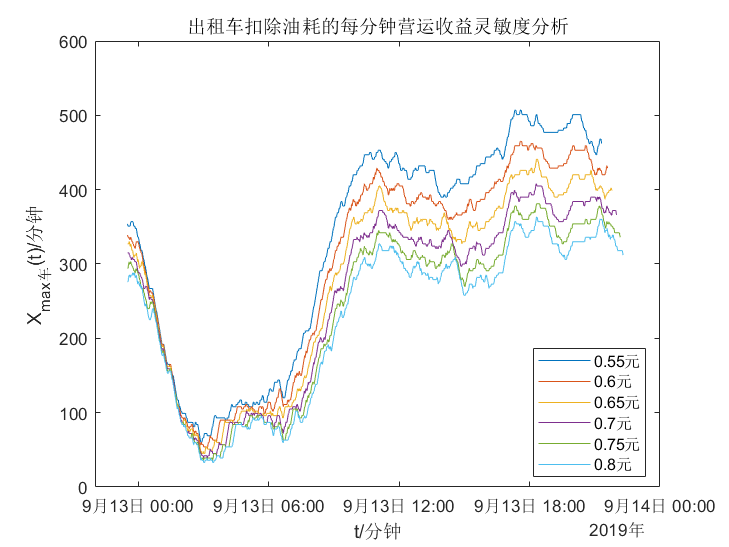

legend('0.55元','0.6元','0.65元','0.7元','0.75元','0.8元','Location',"best")